# SIM 2: Sailbot Data Visualization

**Objective:** 

Explore MATLAB programming techniques for data processing and visualization

**Introduction:**

In the summer of 2018, a Saildrone unmanned surface vehicle (USV) was launched to follow a course along the US/Mexico coast toward Guadalupe Island near Baja California. The USV was deployed to collect measurements in the California Current System. Vist the [Baja Saildrone Project](https://podaac.jpl.nasa.gov/saildrone) site to learn more.

Load the **sailbot_data.mat** file

load("sailbot_data.mat")
sailbot_data;

## Step 1: Mapping

Plot the trajectory of the sailbot using the latitude and longitude values. Add a title and label the axes.

lat = sailbot_data.latitude; % using dot indexing to access table variables
long = sailbot_data.longitude;
plot(long, lat) % plot lat vs. long
title("Sailbot Trajectory")
xlabel("Longitude")
ylabel("Latitude")

The code below adds a map of California using the Mapping Toolbox so you can see where the drone sailed relative to the coast.

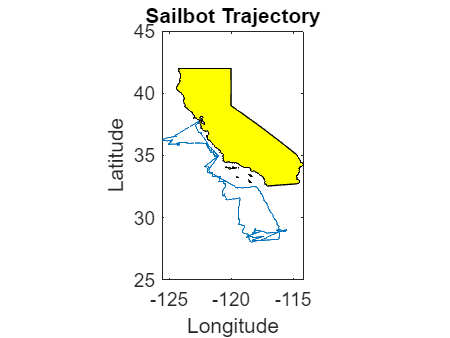

% --- Do Not Edit ---
states = shaperead('usastatehi', 'UseGeoCoords', true);
handle = geoshow(states(5), ...
   'DefaultFaceColor', 'yellow', ...
   'DefaultEdgeColor', 'black');

## Step 2: Wind Speed and Direction

Plot the wind around the coast of California. Bound the plot limits by: 

- **Latitude: **`35.8,` `36.4`

- **Longitude: -122.1, -121.7**

Display the wind velocity as vectors using the `quiver` function. The x component is `wind_speed_u` and the y component is `wind_speed_v`.

Only plot every 4th sample so the arrows don't overlap eachother.

Add a title and label the axes. 

data = sailbot_data(1:4:end,:); % select every 4th sample
quiver(data.longitude,data.latitude,data.wind_speed_u,data.wind_speed_v) % plot wind vectors
xlim([-122.1 -121.7]) % set x-axis limits
ylim([35.8 36.4]) % set y-axis limits
title("Wind")
xlabel("Longitude")
ylabel("Latitude")

The code below adds a map of California using the Mapping Toolbox so you can see where the drone sailed relative to the coast.

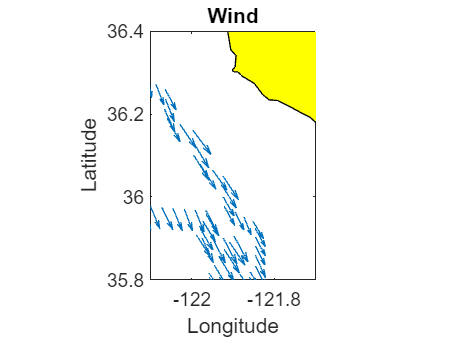

% --- Do Not Edit ---
states = shaperead('usastatehi', 'UseGeoCoords', true);
handle = geoshow(states(5), ...
   'DefaultFaceColor', 'yellow', ...
   'DefaultEdgeColor', 'black');

## Step 3: Air Temperature

Notice the air temperature has many `NaN` entries. This is because the air temperature is sampled every 5 minutes while the other sensors are sampled every minute. Use one or more logical selections to extract the valid air temperatures and their corresponding times from **07:00** **May 11, 2018 **to** 14:00 May 12, 2018. **

Store the results in two new variables called `air_temperature` and `time` respectively.

start_time = find(sailbot_data.time == datetime(2018,5,11,7,0,0)); % set start time 
end_time = find(sailbot_data.time == datetime(2018,5,12,14,0,0)); % set end time
time = sailbot_data.time(start_time:end_time,:); % grab time data between the start and end times
air_temperature = sailbot_data.air_temperature(start_time:end_time,:); % grap air temp data between the start and end times
idx = ~ismissing(air_temperature); % get indexes of available data
time = time(idx); % update time to include only available data
air_temperature = air_temperature(idx); % update air_temperature to include only available data

Use these variables to plot the temperature. Add the average temperature as a dashed red line using `yline`. Make sure your plot has a title, labels, and a legend.

plot(time,air_temperature,"b") % plot air temperature vs time
avg_temp = mean(air_temperature) % calculate the average air temperature

avg_temp = 16.6997

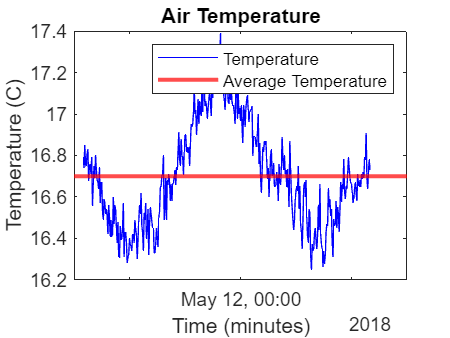

yline(avg_temp,"r","LineWidth",2) % graph the average air temperature
title("Air Temperature")
xlabel("Time (minutes)")
ylabel("Temperature (C)")
legend(["Temperature" "Average Temperature"])

Fit the temperature to a sine wave using the equation below:


$$y=B+A\;\sin \left(Ft+P\right)$$


Where the coeffecients A, B, F, and P can be interpreted as:

- **A **temperature swing (average to peak)

- **B **average temperature

- **F **frequency (hours)

- **P** offset (hours)

The sliders are below are set to cover the appropriate ranges, try figuring out these values on your own first and then use the sliders to understand how changing each parameter affects the result.

peak = max(air_temperature);
A = peak - avg_temp % amplitude calculation

A = 0.6903

B = avg_temp

B = 16.6997

A = 0.45;
B = 16.7;
F = 19;
P = 9;
PERSIST_MODELS = true; % try changing this to true

Run the model and plot the result

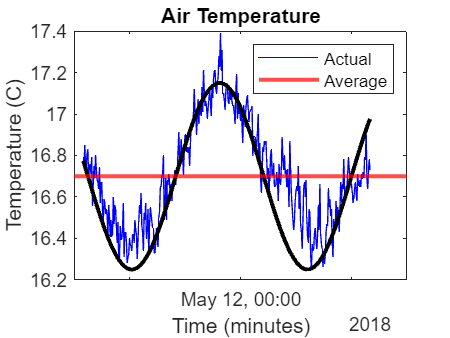

% Do Not Edit
hold on
if ~exist("models","var")
    models = [];
end
if ~exist("time","var")
    fprintf("ERROR: The variable 'time' is missing, did you create it above?");
else
    total_time = minutes((time(end)-time(1)));
    t = 0:5:total_time;
    model = B + A*sin(2*pi/(F*60).*(t+P*60));
    h=plot(time,model,'k','LineWidth',2.0);
    models = [models h];
    if ~PERSIST_MODELS
        delete(models(1:end-1));
    end
    legend('Actual','Average');
end
hold off

## Step 4: Data Analysis

Answer each of the questions below using MATLAB code, use **fprintf** to display your output

**Question 1: **What was the lowest sea temperature and where was it recorded (lat,long)?

[low_temp,low_idx] = min(sailbot_data.water_temperature); % grab min water temp
low_lat = sailbot_data.latitude(low_idx); % grab lat of min water temp
low_long = sailbot_data.longitude(low_idx); % grab long of min water temp
fprintf("Lowest temperature was " + low_long + " at (" + low_lat + ", " + low_long + ").") % display output

Lowest temperature was -122.7743 at (37.6395, -122.7743).

**Question 2:** What was the lowest latitude reached by the saildrone?

bottom_lat = min(sailbot_data.latitude); % grab min latitude 
fprintf("The lowest latitude reached by the salidrone is " + bottom_lat + " degrees.") % display output

The lowest latitude reached by the salidrone is 28.0177 degrees.

**Question 3: **What was the strongest wind magnitude and when was it recorded?

lengths = sqrt(sailbot_data.wind_speed_u .^2 + sailbot_data.wind_speed_v .^2); % calculate length of wind speed vectors
[strong, strong_idx] = max(lengths); % grab max wind speed vector
strong_lat = sailbot_data.latitude(strong_idx); % grab lat of max wind speed vector
strong_long = sailbot_data.longitude(strong_idx); % grab long of max wind speed vector
fprintf("The strongest wind magnitude is " + strong + " which was recorded at " + ...
    strong_lat + " " + strong_long + " degrees.") % display output

The strongest wind magnitude is 15.5108 which was recorded at 35.4325 -121.6662 degrees.